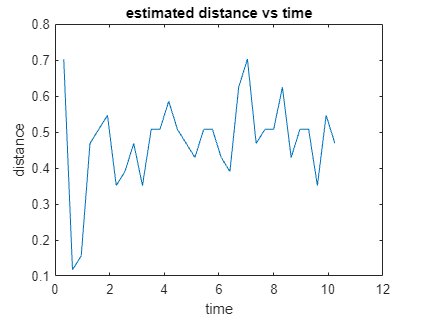

uSq_err = 0.1329


Maximum error for matlab vs simulink distance out of 32 values
absolute : 2.341406e+00
percentage : 3.333333e+02
mse : 1.329236e-01

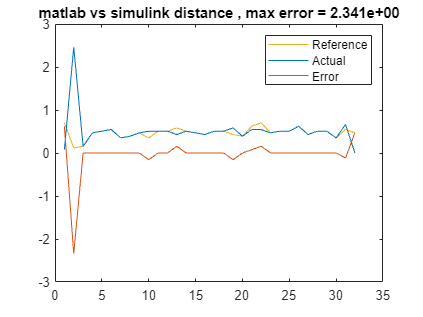

radarReference;

fixedPoint = true;
if(fixedPoint)
    fpDataType = fixdt(1,12,4);
else %else floating point
    fpDataType = "double"
end

%% Simulate model
simTime = length(txSig) + windowLen-nOverlap;
slout = sim('radarSim3');


distSL = getLogged(slout, "dist");
distSL = distSL(windowLen-nOverlap + 1 : end); %remove dead time at start
distSL = downsample(distSL, windowLen-nOverlap);

%compare distance data to matlab
compareData(dist, distSL, {3 1 1}, "matlab vs simulink distance");